fID = fopen("e_th.txt", 'r');
size = [4 Inf];
data = fscanf(fID, "{%f,[%d,%d],%d}\n", size)

data =     0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028
  331.0000  332.0000  333.0000  331.0000  332.0000  333.0000  331.0000  332.0000  333.0000  334.0000  331.0000  332.0000  333.0000  334.0000  332.0000  333.0000  334.0000  332.0000  333.0000  334.0000  332.0000  333.0000  334.0000  335.0000  333.0000  334.0000  335.0000  358.0000  359.0000  360.0000  334.0000  357.0000  358.0000  359.0000  360.0000  361.0000  362.0000  363.0000  364.0000  357.0000  358.0000  359.0000  360.0000  361.0000  362.0000  363.0000  364.0000  365.0000  366.0000  


index = 238000;
time = data(1,index:end)

time =     5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640    5.5640


x_coord = data(2,index:end)

x_coord =    299   300   301   302   303   304   358   359   360   361   362   363   299   300   301   302   303   304   359   360   361   362   363   364   470   471   472   473   474   475   298   299   300   301   302   303   360   361   362   363   364   461   462   463   464   465   466   467   468   469


y_coord = 480.-data(3,index:end)

y_coord =    262   262   262   262   262   262   262   262   262   262   262   262   261   261   261   261   261   261   261   261   261   261   261   261   261   261   261   261   261   261   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260   260


polarity = data(4,index:end)

polarity =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


color = strings(1,length(polarity))

color = 1×214955 string array
  Columns 1 through 5461

    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""  



r_time = []


r_time =

     []



r_x_coord = []


r_x_coord =

     []



r_y_coord = []


r_y_coord =

     []




b_time = []


b_time =

     []



b_x_coord = []


b_x_coord =

     []



b_y_coord = []


b_y_coord =

     []



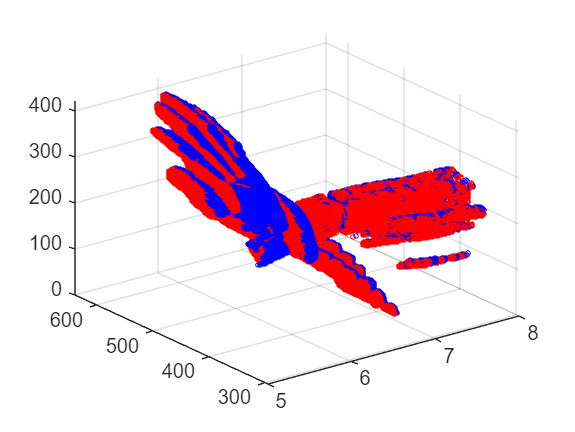


for i = 1 : length(polarity)
    if (polarity(i) == 1)
        r_time(end+1) = time(i);
        r_x_coord(end+1) = x_coord(i);
        r_y_coord(end+1) = y_coord(i);
    else
        b_time(end+1) = time(i);
        b_x_coord(end+1) = x_coord(i);
        b_y_coord(end+1) = y_coord(i);
    end
end


scatter3(r_time, r_x_coord, r_y_coord, 5, "red")
hold on;
scatter3(b_time, b_x_coord, b_y_coord, 5, "blue")